% Clear command window and workspace
clc;
clear;

% --- Aircraft Parameters ---
F_0 = 12000;      % Initial fuel in kg
r = 250;          % Fuel consumption rate in kg/hour

% --- Flight Time Array ---
% Create an array for flight time from 0 to 50 hours with 1-hour intervals
t = 0:1:50; 

% --- Linear Fuel Model ---
% Calculate the remaining fuel for every hour in the array 't'
F_remaining = F_0 - r * t;

% --- Display Selected Values ---
time = [5 10 20]; % Specific flight times to check
fuel = F_0 - r * time; % Calculate remaining fuel for those specific times
disp("Flight Time (hours):");

Flight Time (hours):


disp(time);

     5    10    20



disp("Remaining Fuel (kg):");

Remaining Fuel (kg):


disp(fuel);

       10750        9500        7000




% --- Find Time for Specific Fuel Level ---
% Determine the exact flight time when the fuel reaches 2000 kg
F_required = 2000;
T_flight = (F_0 - F_required) / r;
fprintf("Fuel reaches 2000 kg after %.2f hours\n", T_flight);

Fuel reaches 2000 kg after 40.00 hours


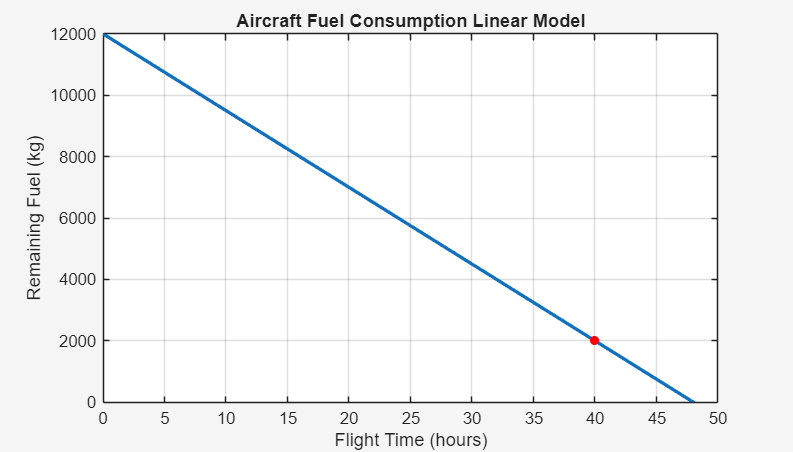


% Define the specific point you want to highlight
y_point = F_required;                    % Y-coordinate
x_point = (F_0 - F_required ) / r;       % X-coordinate

% --- Plotting the Model ---
figure(1); 
clf;

% Plot the main line
plot(t, F_remaining, 'LineWidth', 2);
hold on; % Keep the line visible while adding the point

% Plot the specific point
plot(x_point, y_point, 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r');
hold off; % Release the plot hold

xlabel('Flight Time (hours)');
ylabel('Remaining Fuel (kg)');
title('Aircraft Fuel Consumption Linear Model');
grid on; % Enable grid for better readability
xlim([0 50]);
ylim([0 inf]);
set(gcf, 'WindowStyle', 'docked');